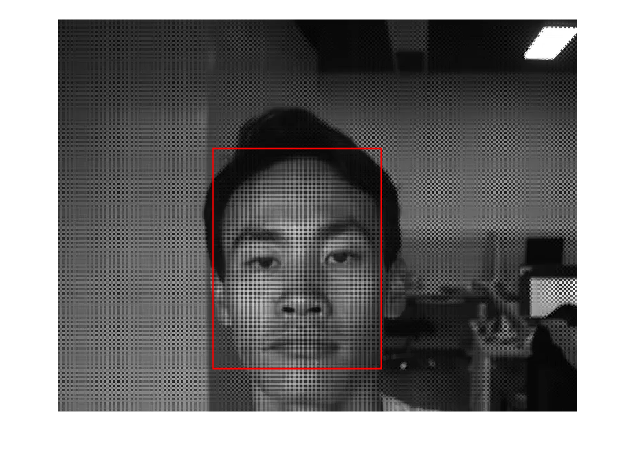

clear; clc; clf;
video = VideoReader('run.mp4');
numFrames = video.NumFrames; %视频帧数
% Video Processing
video = read(video);
Gray_video = zeros(size(video, 1), size(video, 2), size(video, 4));
for i = 1:numFrames
 temp = rgb2gray(video(:,:,:,i));
 Gray_video(:, :, i) = double(temp) / 255;
end
% Define Target Area [column, row, width, height]
Width = 260;
Height = 340;
target_ALL = zeros(numFrames, 4);
target_ALL(1,:) = [240, 200, Width, Height];
figure,
imshow(video(:, :, 1));
hold on
rectangle('Position',target_ALL(1,:), 'EdgeColor','r','LineWidth', 1.0);
hold off

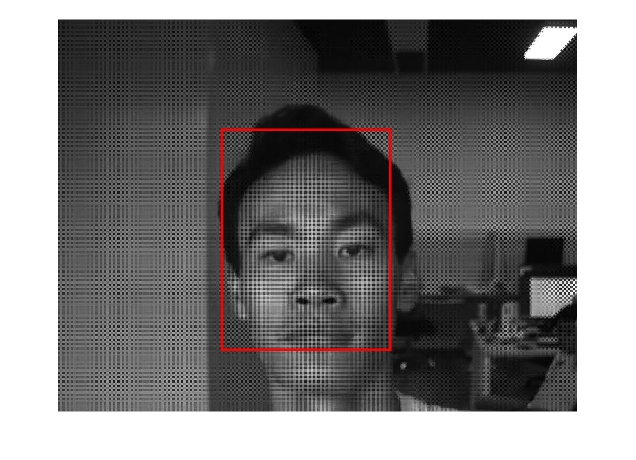

gaussianResponse = fspecial('gaussian', [Height, Width], 3);
lambda = 1;
Malpha = 0.95;
W0 = zeros(Height, Width, numFrames);
W0(:,:,1) = MOSSE(Gray_video(:, :, 1), gaussianResponse, target_ALL(1, :), lambda);
for i = 2 : numFrames
 imshow(Gray_video(:, :, i));
 hold on
 [W_new, frame_cropped] = MOSSE(Gray_video(:, :, i), gaussianResponse, target_ALL(i-1, :), lambda);
 W0(:, :, i) = Malpha*W0(:, :, i-1) + (1-Malpha)*W_new;
 Response = xcorr2(frame_cropped, W0(:,:,i-1));
 k = find(Response==max(Response, [], 'all'));
 [new_x, new_y] = ind2sub(size(Response), k); % 坐标转换
 dx = new_x - Height;
 dy = new_y - Width;
 target_ALL(i, :) = [target_ALL(i - 1, 1) + dy, target_ALL(i - 1, 2) + dx, Width, Height];
 rectangle('Position', target_ALL(i,:),'EdgeColor', 'r','LineWidth', 1.5);
 hold off;
 pause(0.1);
end

function [W, frame_cropped] = MOSSE(img, Y, firstPoint, lambda)
 %img = rgb2gray(img);
 %img = im2double(img);
 [r2, c2] = size(Y);
 X = img(firstPoint(2):firstPoint(2)+r2-1, firstPoint(1):firstPoint(1)+c2-1);
 frame_cropped = X;
 X = fft2(X);
 Y = fft2(Y);
 sxx = X .* conj(X);
 sxy = X .* conj(Y);
 W = sxy ./ (sxx + lambda);
 W = real(ifftshift(ifft2(W)));
 end